# Lab 7 Sessió 1

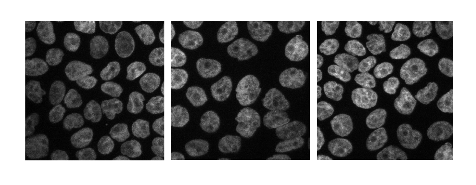

I = rgb2gray(imread('cellsegmentationcompetition.png'));
imshow(I)

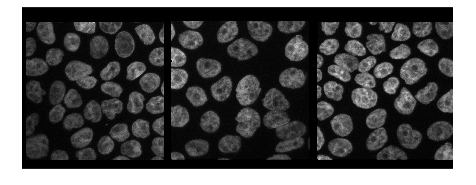


IB = I > 250;
SB = false(size(I));

SB(:, 1) = true;
SB(:, end) = true;
SB(1, :) = true;
SB(end, :) = true;

RB = imreconstruct(SB, IB);
RB = imdilate(RB, ones(6,6));
I(RB) = 0;
imshow(I);

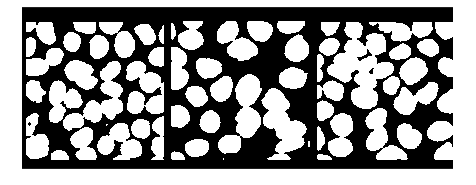


% preprocessat
% filtrat
OI = imopen(I, strel('disk', 4));
CI = imclose(OI, strel('disk', 4));

BW = CI > 20;
imshow(BW);

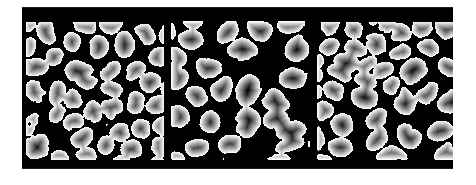


% segmentacio
% per watershed

DT = -bwdist(not(BW));
DT(not(BW)) = -Inf; % pixels del background no s'omplin

DT = imclose(DT, strel('disk', 4));

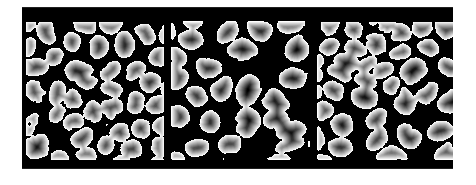

imshow(DT, []);

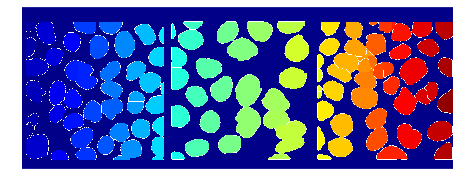


L = watershed(DT);
imshow(label2rgb(L));

## Exercici

#### V1

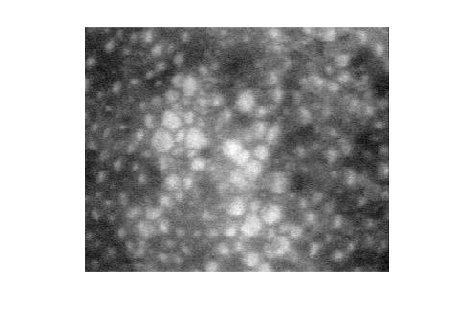

I = imread('cornea.tif');
imshow(I);

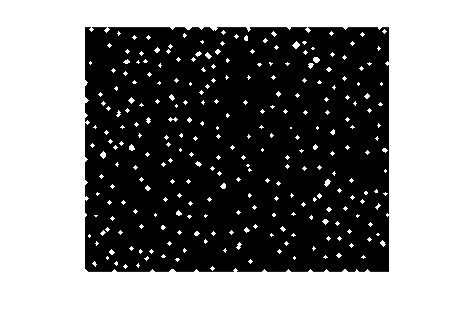


% preprocessat
% filtrat
OI = imopen(I, strel('disk', 2));
CI = imclose(OI, strel('disk', 2));
I = OI;

IRM = imregionalmax(I);
imshow(IRM, []);

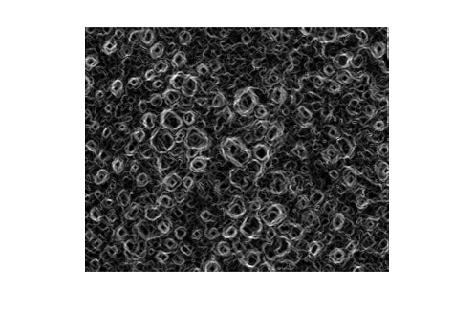


IG = imgradient(I);
imshow(IG, []);

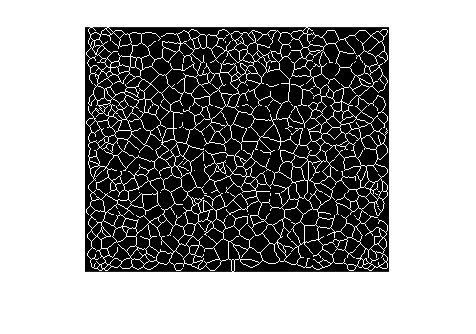


BWIG = imbinarize(IG);

ISkel = bwskel(BWIG);
imshow(ISkel);

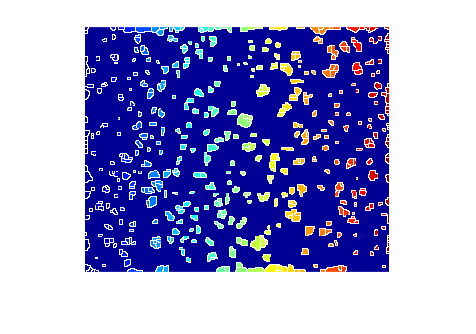


I(ISkel) = -Inf;
I(IRM) = 255;

L = watershed(I);
imshow(label2rgb(L))

#### V2

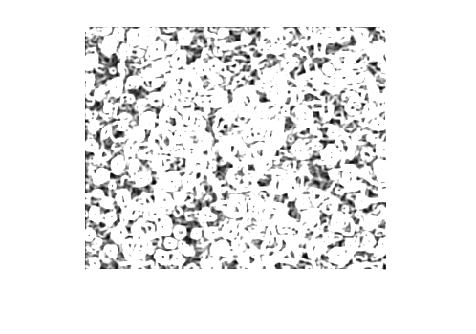

I = imread('cornea.tif');
I = medfilt2(I, [2,2]);

SE = fspecial("disk", 1) > 0;
I = imopen(I, SE);
I = imclose(I, SE);
IRM = imregionalmax(I);

IREC = imreconstruct(I .* uint8(IRM), I);

SK = bwskel(not(IRM));
SKIZ = bwmorph(SK, "spur", Inf);
SKIZ = SKIZ & not(bwhitmiss(SKIZ, [-1 -1 -1; -1 1 -1; -1 -1 -1]));


G = uint8(imgradient(IREC));
G = imfilter(G, ones(3,3));
imshow(G);

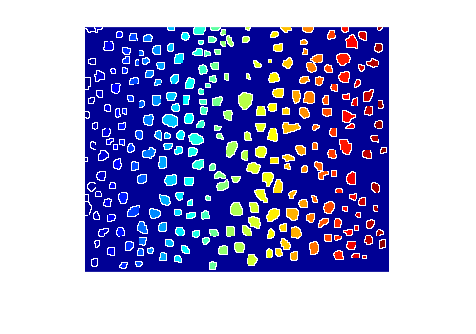


N = imimposemin(G, SKIZ | IRM);

WS = watershed (N);
imshow(label2rgb(WS));

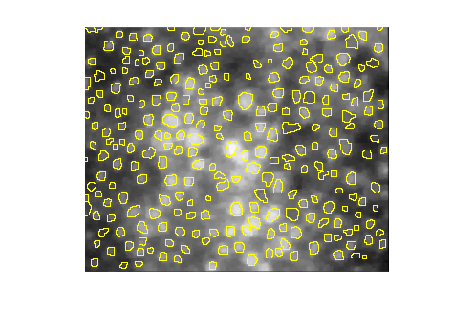


IB = WS == 0;
X = imoverlay(I, IB);
imshow(X);

## Segmentació per kmeans

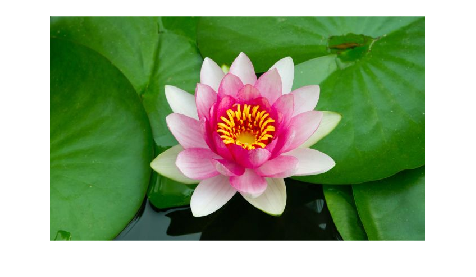

% Reduir el nombre de colors d'una imatge
I = imread('nenufar.jpg');
imshow(I);

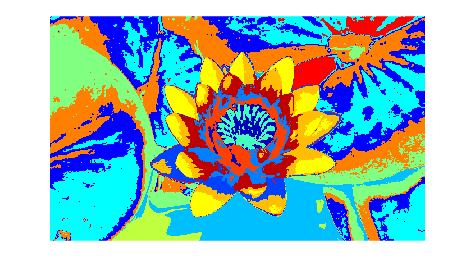


R = I(:, :, 1);
G = I(:, :, 2);
B = I(:, :, 3);

O = [R(:), G(:), B(:)];

IKM = kmeans(double(O), 15);

[f, c, p] = size(I);

Result = reshape(IKM, [f, c]);

imshow(label2rgb(Result), []);